load ('Samsung_30Q_18650_pack.mat');
load ('VoltaicSystems_P110.mat');

addpath(genpath("Functions"));
addpath("Simulink/");

picture_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Slike_CV";
mat_files_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Mat_files";

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Granicni uvjet filter:
boost.Tgf = 1/(pi*1000);


% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 100 * 10^-3;
boost.Ru = 1;
boost.L = 40 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = (Bat.Qbat_tot)/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## PV resistance:

% CCM:
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_ccm = calc_pv_res("Solar_v2", pv_in);

% DCM
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_dcm = calc_pv_res("Solar_v2", pv_in);

clear pv_in;

## Pick operating point:

% Pick operating point for simulation:

% CCM:
Upv_op = pv_ccm.Umpp;
idx = find(pv_ccm.Upv >= Upv_op, 1);
Ipv_op = pv_ccm.Ipv(idx);

ccm_in.Upv_op = Upv_op;
ccm_in.Ipv_op = Ipv_op;

%DCM
Upv_op = pv_dcm.Umpp;
idx = find(pv_dcm.Upv >= Upv_op, 1);
Ipv_op = pv_dcm.Ipv(idx);

dcm_in.Upv_op = Upv_op;
dcm_in.Ipv_op = Ipv_op;

clear idx;
clear Upv_op Ipv_op;

## Step input Settings:

% Step input settings:
stepp.step_time = 30 * 10^-3; % [ms]
% stepp.sim_time = 50 * 10^-3; % [ms]
stepp.sim_time = 0.5;

% Ir, Refrence current:
stepp.ir01 = pv_ccm.Impp;
stepp.ir02 = pv_ccm.Impp + 0.05;

[~, idx1] = min(abs(pv_ccm.Ipv - stepp.ir01));
[~, idx2] = min(abs(pv_dcm.Ipv - stepp.ir02));

stepp.upv1 = pv_ccm.Upv(idx1);
stepp.upv2 = pv_dcm.Upv(idx2);

% CCM:
stepp.d1 = calc_duty_cycle_CV(boost, Bat, pv_ccm, stepp.upv1, stepp.ir01, 12.4);
stepp.d2 = calc_duty_cycle_CV(boost, Bat, pv_ccm, stepp.upv2, stepp.ir02, 12.4)

stepp = struct with fields:
    step_time: 0.0300
     sim_time: 0.5000
         ir01: 1.4690
         ir02: 1.5190
         upv1: 5.7000
         upv2: 5.4290
           d1: 0.5403
           d2: 0.5622



bla = ccm_op_CV(boost, Bat, pv_ccm);
bla.Im0

ans = 0.5865

bla.Ipv0

ans = 1.4690

bla.Upv0

ans = 5.7000


clear idx1 idx2;

## Irradiance signal:

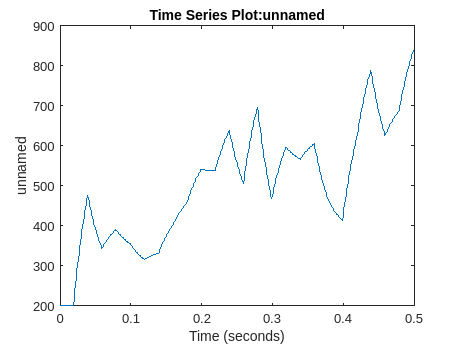

GI_signal = Irradiance_signal(stepp.sim_time, 0.02, 200, 1000);

figure();
GI_signal.plot();

## Steady state operating point parameters:

% CCM mode with compensation ramp parameters:
ccm_op_cv = ccm_op_CV(boost, Bat, pv_ccm);
display('CCM parameters:')

CCM parameters:


Upv0 = ccm_op_cv.Upv0

Upv0 = 5.7000

Ipv0 = ccm_op_cv.Ipv0

Ipv0 = 1.4690

Ubat0 = ccm_op_cv.Ubat0

Ubat0 = 12.4000

Im0 = ccm_op_cv.Im0

Im0 = 0.5865

m0 = ccm_op_cv.m0

m0 = 2.0825e+04

ro = ccm_op_cv.ro

ro = 0.6812

L_lim = ccm_op_cv.L_lim

L_lim = 5.2783e-05

G_incr_pv = ccm_op_cv.G_incr_pv

G_incr_pv = -0.2577

D0 = ccm_op_cv.D0

D0 = 0.5403

Ir_lim = ccm_op_cv.Ir_lim

Ir_lim = 0.8825


% DCM mode parameters:
dcm_op_cv = dcm_op_CV(boost, Bat, pv_dcm);
disp('DCM parameters:')

DCM parameters:


Upv0 = dcm_op_cv.Upv0

Upv0 = 5.7000

Ipv0 = dcm_op_cv.Ipv0

Ipv0 = 1.4690

Ubat0 = dcm_op_cv.Ubat0

Ubat0 = 12.4000

m0 = dcm_op_cv.m0

m0 = 2.0825e+04

ro = dcm_op_cv.ro

ro = 1.4524

G_incr_pv = dcm_op_cv.G_incr_pv

G_incr_pv = -0.2577

D0 = dcm_op_cv.D0

D0 = 0.8994


sim_op = ccm_op_cv;
% sim_op.Ubat0 = 11.8;

clear Upv0 Ipv0 Ir0 Ubat0 Im0 m0 ro L_lim D0 G_incr_pv

## Colors:

myColors = [
    0, 0, 0;                    % black
    0, 0, 1;                    % blue
    1, 0, 0;                    % red
    0, 1, 0;                    % green
];

## CCM,CV (compensation ramp):

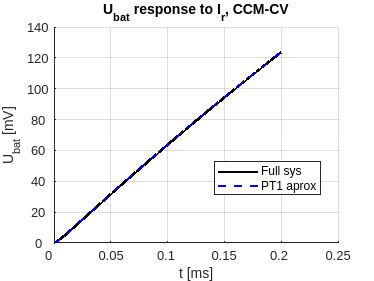

[ccm_constants_cv, ccm_tfs_cv] = ccm_tfs_CV(boost, ccm_op_cv);

plot_data.t = linspace(0, 0.2*10^-3,1000);
plot_data.labels = {"Full sys", "PT1 aprox"};
plot_data.colors = myColors;
plot_data.linestyles = {'-','--'};
plot_data.y_label = "U_b_a_t [mV]";

% Refrence current:
plot_data.fgtitle = "U_b_a_t response to I_r, CCM-CV";

Ir.full = ccm_tfs_cv.G_Ubat_Ir;
Ir.red = ccm_tfs_cv.G_Ubat_Ir;

plot_step_responses(Ir, plot_data);

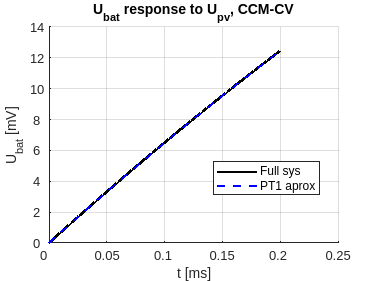


% Input voltage:
plot_data.fgtitle = "U_b_a_t response to U_p_v, CCM-CV";

Upv.full = ccm_tfs_cv.G_Ubat_Upv;
Upv.red = ccm_tfs_cv.G_Ubat_Upv_red;

plot_step_responses(Upv, plot_data);


Gipv = ccm_tfs_cv.G_Ubat_Ir

Gipv =
 
       2.009e-06 s + 0.7785
  ------------------------------
  6.011e-09 s^2 + 0.001146 s + 1
 
Continuous-time transfer function.
Model Properties


Gupv = ccm_tfs_cv.G_Ubat_Upv

Gupv =
 
       4.15e-07 s + 0.07743
  ------------------------------
  6.011e-09 s^2 + 0.001146 s + 1
 
Continuous-time transfer function.
Model Properties



% Plot poles and zeros:
Gz = {ccm_tfs_cv.G_Ubat_Ir, ccm_tfs_cv.G_Ubat_Upv};

fig = plot_p_and_z(Gz, ccm_tfs_cv.G_Ubat_Ir, '$Polovi/Nule$');

Current plot released


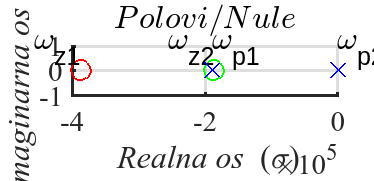

exportgraphics(gcf, "PZ_ccm.png", 'Resolution', 300);



clear Tp1 Tp2 Tz1 Tz2 Zeta;
clear Gupv Gipv;
clear Upv Ir;
clear plot_data;

## DCM, CV

[dcm_constants_cv, dcm_tfs_cv] = dcm_tfs_CV(boost, dcm_op_cv);

dcm_tfs_cv.G_Ubat_Ir_full

ans =
 
       1.414e08 s + 6.676e04
  --------------------------------
  2.541e05 s^2 + 2.273e08 s + 7320
 
Continuous-time transfer function.
Model Properties



dcm_tfs_cv.G_Ubat_Upv_full

ans =
 
         2.014e07 s + 9513
  --------------------------------
  2.541e05 s^2 + 2.273e08 s + 7320
 
Continuous-time transfer function.
Model Properties


## Plant model:

% CCM-CV:
[Gp_ccm_cv, ccm_sys_const_cv] = ccm_sys_CV(ccm_constants_cv, ccm_op_cv, boost);

1/ccm_sys_const_cv.Tp1

ans = 171.8079

1/ccm_sys_const_cv.Tp2

ans = 876.5264

1/ccm_sys_const_cv.Tp3

ans = 1.2566e+04

1/ccm_sys_const_cv.Tz

ans = 126.6397


Gp_ccm_cv

Gp_ccm_cv =
 
               0.004531 s + 0.5739
  ----------------------------------------------
  5.284e-10 s^3 + 7.194e-06 s^2 + 0.007041 s + 1
 
Continuous-time transfer function.
Model Properties



% DCM-CV:
[Gp_dcm_cv, dcm_sys_const_cv] = dcm_sys_CV(dcm_constants_cv, dcm_op_cv, boost);

1/dcm_sys_const_cv.Tp1

ans = 171.8079

1/dcm_sys_const_cv.Tp2

ans = 894.3330

1/dcm_sys_const_cv.Tp3

ans = 1.2566e+04

1/dcm_sys_const_cv.Tz

ans = 33.8440


dcm_sys_const_cv.K

ans = 0.1225


Gp_dcm_cv

Gp_dcm_cv =
 
               0.003621 s + 0.1225
  ---------------------------------------------
  5.179e-10 s^3 + 7.06e-06 s^2 + 0.007018 s + 1
 
Continuous-time transfer function.
Model Properties


## CCM & DCM SO regulators:

[G_ccm_full, ccm_reg_param] = SO_regulator(Gp_ccm_cv, ccm_sys_const_cv);
ccm_reg_param.KR

ans = 5.1562

ccm_reg_param.Ti

ans = 0.0010


[G_dcm_full, dcm_reg_param] = SO_regulator(Gp_dcm_cv, dcm_sys_const_cv);
dcm_reg_param.KR

ans = 6.3244

dcm_reg_param.Ti

ans = 0.0010


cv_m0 = ccm_op_cv.m0

cv_m0 = 2.0825e+04


save(mat_files_path + "/CV_param.mat", "ccm_reg_param", "dcm_reg_param", "cv_m0");

clear cv_m0;

## Bode plot

% Odredit ulazne parametre:
Gp = Gp_dcm_cv;

z = zero(Gp);
p = pole(Gp);
[~, idx_z] = sort(abs(z), 'ascend'); % Sort zeros by magnitude
[~, idx_p] = sort(abs(p), 'ascend'); % Sort poles by magnitude
z_sorted = abs(z(idx_z));
p_sorted = abs(p(idx_p));

p_sorted

p_sorted = 1.0e+04 *

    0.0172
    0.0894
    1.2566


z_sorted

z_sorted = 33.8440

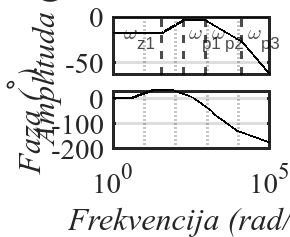


w = logspace(0, 5, 1000);

% figure();
% bode(Gp_ccm);
% grid on;

fig = draw_bode(Gp, w);
exportgraphics(gcf, picture_path + "/bode_dcm_CV.png", 'Resolution', 300);


clear z p;
clear idx_z idx_p;
clear z_sorted p_sorted;

## Regulator (symmetrical optimum), textbook:

% Operating point:
sim_op = ccm_op_cv;

Unrecognized function or variable 'ccm_op'.


Kp = plant_ccm_param.K;
Tsum = plant_ccm_param.Tp2 + plant_ccm_param.Tp3;
Ti = 4*Tsum;
KR = 1/Kp*Ti/(2*Tsum);
GR = tf([KR*Ti, KR], [Ti, 0])

G_full = GR * Gp_ccm;

draw_bode(G_full, w);

w = logspace(0, 5, 1000);

figure();
bode(G_full, w);
grid on;

## Regulator (symmetrical optimum), bjazic

% Odredit ulazne parametre:
Gp = Gp_dcm_cv;
param = dcm_sys_const_cv;

% SO:
PM = 50;
a = PM/14;

% System poles:
wz = 1/param.Tz;
wp1 = 1/param.Tp1;
wp2 = 1/param.Tp2;
wp3 = 1/param.Tp3;
wc = wp3/a

wc = 3.5186e+03

wi = wc/a

wi = 985.2035

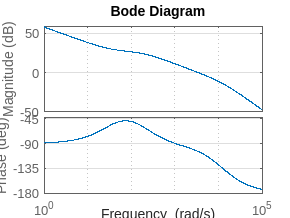



dL1 = -20*log10(wi/wc);
dL2 = -40*log10(wp2/wi);
dL3 = -20*log10(wp1/wp2);
dL4 = -20*log10(1/wz);

Ko = 10^((dL4 + dL3 + dL2 + dL1)/20);
Ti = 1/wi;
KR = (Ko*Ti)/(param.K);

Gr = tf([KR, KR/Ti], [1, 0]); 

G_full = Gr * Gp;

w = logspace(0, 5, 1000);

figure();
bode(G_full, w);
grid on;

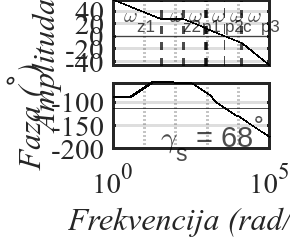


z = zero(G_full);
p = pole(G_full);
[~, idx_z] = sort(abs(z), 'ascend'); % Sort zeros by magnitude
[~, idx_p] = sort(abs(p), 'ascend'); % Sort poles by magnitude
z_sorted = abs(z(idx_z));
p_sorted = abs(p(idx_p));

fig = draw_bode(G_full, w);
exportgraphics(gcf, picture_path + "/bode_dcm_full_CV.png", 'Resolution', 300);

## CCM vs DCM:

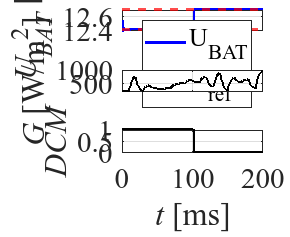

CV_response = sim("Regulacija_sim/constant_volt.slx");
t = CV_response.get("Ubat").Time * 1000;
Ubat = CV_response.get("Ubat").Data;
Gir = CV_response.get("Gir").Data;
t_dcm = CV_response.get("DCM").Time * 1000;
DCM = CV_response.get("DCM").Data;

step = 10;  % plot every 10th sample (you’ll still have 1000 pts over 0.1s)
t_plot = t(1:step:end);
Ubat_plot = Ubat(1:step:end);
Gir_plot = Gir(1:step:end);
DCM_plot = DCM(1:step:end);

% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 3 x 1 array of graphs:
layout = tiledlayout(3,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

nexttile;
plot(t, Ubat, '-b', 'LineWidth', 1.8);
hold on;
yline(12.42, '--r', 'LineWidth', 1.6);
yline(12.7, '--r', 'LineWidth', 1.6);
grid on;
ylabel("\it{U_{BAT}}\rm [V]");
legend("U_{BAT}", "U_{ref}");
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

nexttile;
plot(t, Gir, '-k', 'LineWidth', 1.6);
grid on;
ylabel("\it{G}\rm [W/m^2]");
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

nexttile;
stairs(t_dcm, DCM, '-k', 'LineWidth', 1.6);
grid on;
ylabel("\it{DCM}\rm");
xlabel("\it{t}\rm [ms]");
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'LineWidth', 1.2);


exportgraphics(gcf, picture_path + "/CV_sim.png", 'Resolution', 300);

## linear vs nonlinear (system tf):

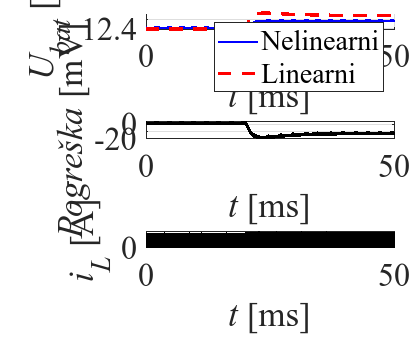

sim_op = dcm_op_cv;

lin = sim("Simulink/Strujni_nacin_v2.slx");

nonlin = sim("Simulink/Nelinearni_test.slx");

% Extract
IL_nonlin = nonlin.get("IL").Data;
Ubat_nonlin = nonlin.get("Ubat").Data;
Ubat_lin = lin.get("Ubat").Data;
t = lin.get("Ubat").Time * 1000;  % convert to ms

% Time period to cut from graph (10 ms)
t_start = 10;  % [ms]
idx = t >= t_start;

% Shorten arrays
t = t(idx) - t_start;
IL_nonlin = IL_nonlin(idx);
Ubat_nonlin = Ubat_nonlin(idx);
Ubat_lin = Ubat_lin(idx);

% % Set paper properties on the figure
% fig.PaperUnits = 'centimeters';
% fig.PaperSize = [21 29.7];           % width x height in inches
% fig.PaperPosition = [0 0 8 4.5];   % position on paper (fill whole paper)

% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 3 x 1 array of graphs:
layout = tiledlayout(3,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

% Output voltage:
nexttile;
hold on;
plot(t, Ubat_nonlin, 'b', 'LineWidth', 1.5);
plot(t, Ubat_lin, '--r', 'LineWidth', 2.5);
hold off;
xlabel("\it{t}\rm [ms]");
ylabel("\it{U_{bat}}\rm [V]");
legend("Nelinearni", "Linearni");
axis auto;
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Error:
nexttile;
error = (Ubat_nonlin - Ubat_lin)*1000;
plot(t, error, 'k', 'LineWidth', 1.5);
ylabel("\it{Pogreška}\rm [mV]");
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Struja zavojnice:
nexttile;
plot(t, IL_nonlin, 'k', 'LineWidth', 1.5);
ylabel("\it{i_L}\rm [A]");
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

exportgraphics(gcf, picture_path + "/graf_dcm_full.png", 'Resolution', 300);

## Plot PV characteristic:

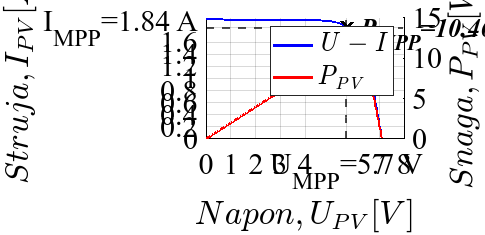

% pv_in.G = 1000;     %[W/m^2]
% pv_in.t = 25;       %[deg]
% pv_in.ramp = 1;     %[/]
% pv = calc_pv_res("Solar_v2", pv_in);

% for 11 x 9 (W x H)
width_px = round(15.52/2.54 * 300); % ~1335 pixels
height_px = round(7.5/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels','Position',[100 100 width_px height_px]);

% Set default font for axes and text within this figure
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

hold on;
grid on;

% --- Left axis: I-V curve ---
yyaxis left
hI = plot(pv.Upv, pv.Ipv, '-b', 'LineWidth', 2);
ylabel("${Struja, I_{PV} [A]}$", 'Interpreter', 'latex');

% Incremental conductance:
% Ir = 0;
% U1 = interp1(pv.Ipv, pv.Upv, Ipv0, 'linear', 'extrap');
% idx = find(pv.Upv >= U1, 1);
% Gpv = (pv.Ipv(idx+1) - pv.Ipv(idx-1)) / (pv.Upv(idx+1) - pv.Upv(idx-1))
% x = linspace(pv.Upv(idx) - 0.5, pv.Upv(idx) + 0.5, 200);
% y = pv.Ipv(idx) + Gpv * (x - pv.Upv(idx));
% hold on;
% plot(x, y, '-r', 'LineWidth', 1.3);

% --- Right axis: P-V curve (still black) ---
yyaxis right
hP = plot(pv.Upv, pv.Ppv, '-r', 'LineWidth', 2);
ylabel("${Snaga, P_{PV} [W]}$", 'Interpreter', 'latex');

lgd = legend([hI hP], {'$\it{U-I}$', '$\it{P_{PV}}$'}, 'Location','northeast');
set(lgd, 'Interpreter', 'latex');
lgd.AutoUpdate = 'off';

% --- Set both axes black ---
ax = gca;
ax.YColor = 'k';
ax.XColor = 'k';

% --- Common x-axis ---
xlabel("${Napon, U_{PV} [V]}$", 'Interpreter', 'latex');

% --- Add MPP markers ---
yyaxis left
plot(pv.Umpp, pv.Impp, 'xk', 'MarkerSize', 10, 'LineWidth', 3);  % I-V curve
yyaxis right
plot(pv.Umpp, pv.Pmpp, 'xk', 'MarkerSize', 10, 'LineWidth', 3);  % P-V curve

% --- Add Pmpp text label ---
text(pv.Umpp, pv.Pmpp, ...
    sprintf('  P_{MPP}=%.2f W', pv.Pmpp), ...
    'VerticalAlignment','bottom','HorizontalAlignment','left', ...
    'FontSize',20,'FontName','Times New Roman', ...
    'FontWeight','bold','FontAngle','italic', ...
    'Interpreter','tex');
% --- MPP guide lines ---
yyaxis left
xline(pv.Umpp, '--k', 'LineWidth', 1.5);   % vertical line at Umpp
yline(pv.Impp, '--k', 'LineWidth', 1.5);   % horizontal line at Impp

% --- Add x/y ticks only for MPP and remove overlap ---
xt = xticks;
yt = yticks;

% Remove ticks too close to Umpp / Impp (optional)
xt(abs(xt - pv.Umpp) < 0.2 * pv.Umpp) = [];
yt(abs(yt - pv.Impp) < 0.1 * pv.Impp) = [];

% Add the MPP tick positions back
xt = sort([xt, pv.Umpp]);
yt = sort([yt, pv.Impp]);

% Build new labels
xtlbl = string(xt);
ytlbl = string(yt);

% Label Umpp and Impp
[~, ix] = min(abs(xt - pv.Umpp));
xtlbl(ix) = sprintf('U_{MPP}=%.1f V', pv.Umpp);

[~, iy] = min(abs(yt - pv.Impp));
ytlbl(iy) = sprintf('I_{MPP}=%.2f A', pv.Impp);

% Apply new ticks and labels
xticks(xt);
yticks(yt);
xticklabels(xtlbl);
yticklabels(ytlbl);
ax = gca;
ax.XTickLabelRotation = 0;

% --- Final formatting ---
set(gca, 'TickLabelInterpreter', 'tex');
set(findall(gcf,'type','text'), 'Color', 'k');

% --- Set both axes black ---
ax = gca;
ax.YColor = 'k';
ax.XColor = 'k';

grid on;

exportgraphics(gcf, picture_path + '/graf_pv_characteristic.png', 'Resolution', 300);

## Pole and zero plot:

% for 11 x 9 (W x H)
width_px = round(15.52/2.54 * 300); % ~1335 pixels
height_px = round(7.5/2.54 * 300); % ~1146 pixels


Unable to resolve the name 'ccm_m_separate_tfs.G_Ubat_Ir'.


fig = figure('Units','pixels','Position',[100 100 width_px height_px]);

%% --- Compute text offset based on axis scale ---
ax = gca;
xrange = diff(ax.XLim);
yrange = diff(ax.YLim);

% dx = 0.05 * xrange;   % larger offset than before
% dy = 0.03 * yrange;

% Set default font for axes and text within this figure
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

z1 = zero(ccm_m_separate_tfs.G_Ubat_Ir);
z2 = zero(ccm_m_separate_tfs.G_Ubat_Upv);
p = pole(ccm_m_separate_tfs.G_Ubat_Upv);
p2 = p(1);
p1 = p(2);
clear p;

hz1 = plot(real(z1), imag(z1), 'ro', 'MarkerSize', 15, 'LineWidth', 2); hold on;
text(real(z1), imag(z1), 'ω_{z1}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

hz2 = plot(real(z2), imag(z2), 'go', 'MarkerSize', 15, 'LineWidth', 2);
text(real(z2), imag(z2), 'ω_{z2}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

plot(real(p1), imag(p1), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p1), imag(p1), 'ω_{p1}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

plot(real(p2), imag(p2), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p2), imag(p2), 'ω_{p2}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

grid on;
% xlabel('$Realna$ $os$ (σ)', 'Interpreter', 'latex');
% ylabel('$Imaginarna$ $os$ (jω)', 'Interpreter', 'latex');
xlabel('\it Realna os \rm (\sigma)', 'Interpreter', 'tex');
ylabel('\it Imaginarna os \rm (j\omega)', 'Interpreter', 'tex');
title('$Polovi/Nule$', 'Interpreter', 'latex');

%% --- Legend (zeros only, color-linked) ---
% legend([hz1, hz2], {'$T_{z1}$', '$T_{z2}$'}, ...
%     'Interpreter', 'latex', ...
%     'Location','northeast');

hold off;

exportgraphics(gcf, picture_path + "graf_ccm_pz.png", 'Resolution', 300);